# **ECON 310: Dynamic Macroeconomics - Problem Set 2**

### **Vu Thi Khanh Ngoc - 220174 **

### **Spring 2025**

### **Fulbright University Vietnam**

## **Part I: Modeling Households in Vietnam**

Consider the life cycle model with borrowing constraints, where the representative household lives up to age$ \(T - 1\). The household works and receives exogenous labor income, \(y_t\), for the first \(t_r - 1\) years of life. After that, the household retires and receives a pension, \(\kappa \, y_{t_r - 1}\), from age \(t_r\) to \(T - 1\), where \(0 < \kappa < 1\) and \(y_{t_r - 1}\) is the household's labor income in the last year of working life.

The household maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period.

The optimization problem is given by:$


$$\[
\max_{\{c_t\}_{t=0}^{T-1}, \{a_{t+1}\}_{t=0}^{T-1}} \quad U = \sum_{t=0}^{T-1} \beta^t \frac{c_t^{1-\gamma}}{1 - \gamma}
\]

\text{st:}
\[
a_{t+1} = (1 + r)(a_t + y_t - c_t)
\]

\[
y_t = 
\begin{cases} 
G_t \exp(\rho \log y_{t-1} + \epsilon_t) & \text{if } t < t_r \\
\kappa \, y_{t_r-1} & \text{if } t \geq t_r
\end{cases}
\]

\[
a_t \geq 0, \quad c_t > 0, \quad a_T = 0
\]

$$


Where : 


$$
|\rho| < 1 , \(G_t\) represents the age-specific average income. The income shock follows a normal distribution: $\epsilon_t \sim \mathcal{N}(0, \sigma^2)$
$$


### Set up the directory

clc;
clear;
close all;

### Plot age specific income graph for each age

% Load raw Gt
Gt_bin = prepare_income("household_data.csv");

Alpha not provided, using default value: 0.50
Education Distribution:
Education Level 0: 21.57%
Education Level 1: 27.67%
Education Level 2: 31.93%
Education Level 3: 14.10%
Education Level 4: 0.00%
Education Level 5: 0.00%
Education Level 6: 0.00%
Education Level 7: 0.00%
Education Level 8: 0.82%
Education Level 9: 3.63%
Education Level 10: 0.13%
Education Level 11: 0.07%
Education Level 12: 0.07%

Education Multiplier (ψ) for α = 0.50:
Education Level 0: ψ = 1.000
Education Level 1: ψ = 1.042
Education Level 2: ψ = 1.083
Education Level 3: ψ = 1.125
Education Level 4: ψ = 1.167
Education Level 5: ψ = 1.208
Education Level 6: ψ = 1.250
Education Level 7: ψ = 1.292
Education Level 8: ψ = 1.333
Education Level 9: ψ = 1.375
Education Level 10: ψ = 1.417
Education Level 11: ψ = 1.458
Education Level 12: ψ = 1.500

Age and Education Specific Income (Gt_matrix):
   1.0e+05 *

    0.2053    0.2053    0.3236    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.

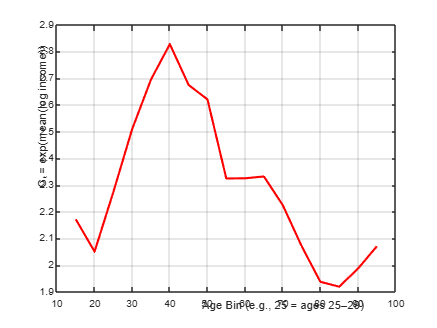

% Plot full Gt profile
my_graph.plot_gt(Gt_bin);

### **Run the stimulation for baseline model**

if length(Gt_bin.AgeBin) >= 2
    Gt_interp = interp1(Gt_bin.AgeBin, Gt_bin.Gt, 0:60, 'linear', 'extrap');
else
    error('Insufficient age bins for interpolation.');
end

% Setup model
par = model.setup();
par.Gt = Gt_interp(:);  % length = 61
par = model.gen_grids(par);

% Solve and simulate
sol = solve.lc(par);

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------


sim = simulate.lc(par, sol);


Baseline Model Simulation Completed.


### Policy functions for consumption and wealth for the baseline model

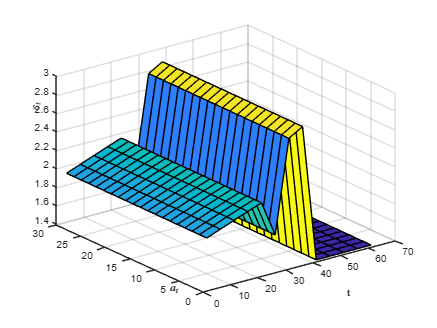

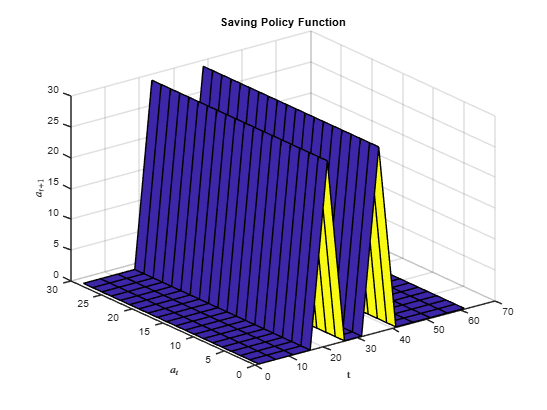

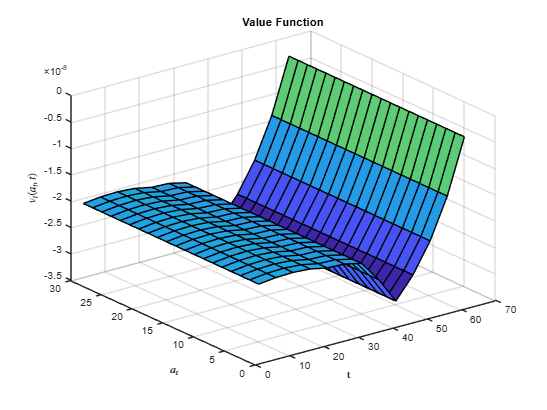

my_graph.plot_policy(par, sol, sim);

### Life cycle profiles of consumption and wealth for baseline model

% Run baseline model
sol = solve.lc(par);

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------


sim = simulate.lc(par, sol);


Baseline Model Simulation Completed.


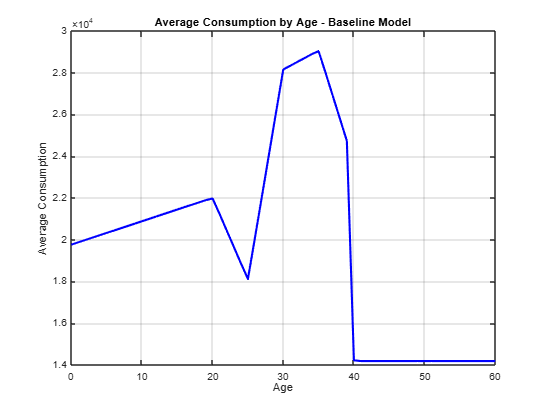

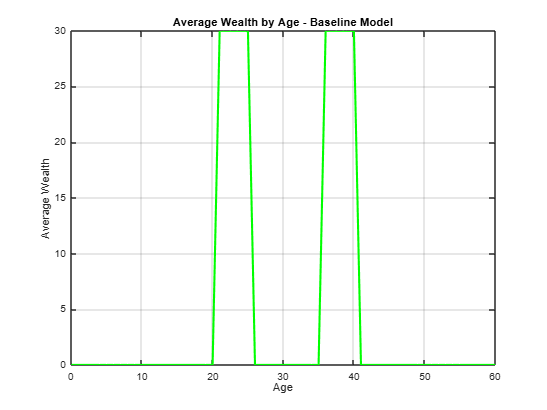

my_graph.plot_lifecycle_profiles(par, sim, 'Baseline Model');

### Model for different values of β and γ

%% Part 1: Vary beta (gamma = 2.00)
gamma_fixed = 2.00;
betas = [0.90, 0.92, 0.94, 0.96];
avg_c_beta = cell(length(betas), 1);
avg_a_beta = cell(length(betas), 1);

for i = 1:length(betas)
    par = model.setup();
    par.beta = betas(i);
    par.sigma = gamma_fixed;
    par = model.gen_grids(par);
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    [avg_c, avg_a] = my_graph.average_profiles(par, sim);
    avg_c_beta{i} = avg_c;
    avg_a_beta{i} = avg_a;
end

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


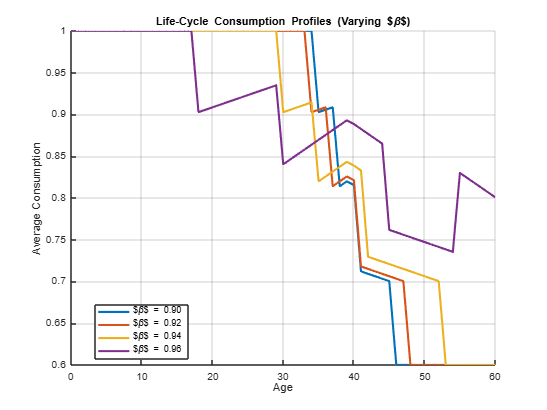


% Plot results
my_graph.plot_multiple_profiles(par, avg_c_beta, betas, '$\beta$', 'Consumption');

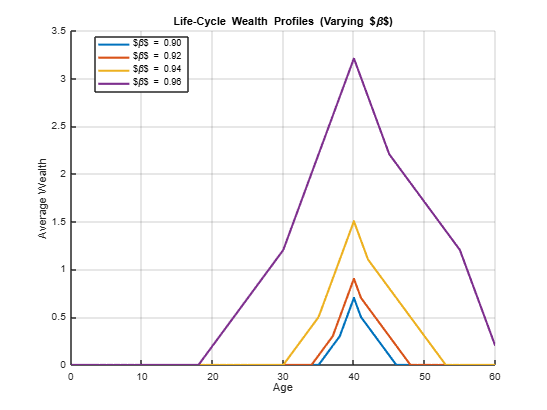

my_graph.plot_multiple_profiles(par, avg_a_beta, betas, '$\beta$', 'Wealth');


% Plot results
my_graph.plot_multiple_profiles(par, avg_c_beta, betas, '$\beta$', 'Consumption');

my_graph.plot_multiple_profiles(par, avg_a_beta, betas, '$\beta$', 'Wealth');



%% Part 2: Vary gamma (beta = 0.96)
beta_fixed = 0.96;
gammas = [2.00, 3.00, 4.00, 5.00];
avg_c_gamma = cell(length(gammas), 1);
avg_a_gamma = cell(length(gammas), 1);

for j = 1:length(gammas)
    par = model.setup();
    par.beta = beta_fixed;
    par.sigma = gammas(j);
    par = model.gen_grids(par);
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    [avg_c, avg_a] = my_graph.average_profiles(par, sim);
    avg_c_gamma{j} = avg_c;
    avg_a_gamma{j} = avg_a;
end

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


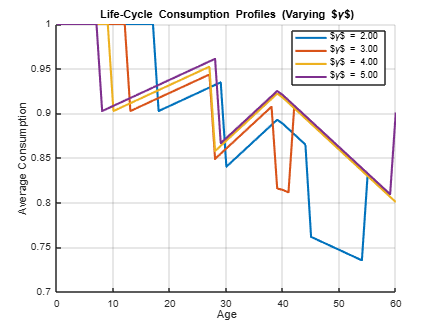


% Plot results
my_graph.plot_multiple_profiles(par, avg_c_gamma, gammas, '$\gamma$', 'Consumption');

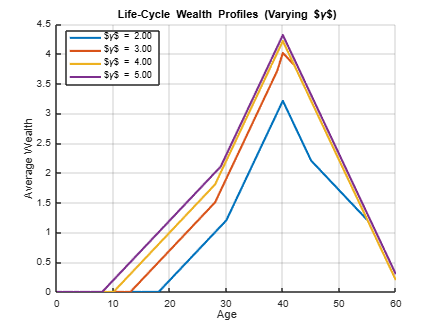

my_graph.plot_multiple_profiles(par, avg_a_gamma, gammas, '$\gamma$', 'Wealth');

%% Part 3: Heatmap (vary both beta and gamma)
betas_heat = [0.90, 0.92, 0.94, 0.96];
gammas_heat = [2.00, 3.00, 4.00, 5.00];
avg_wealth_matrix = zeros(length(betas_heat), length(gammas_heat));

for i = 1:length(betas_heat)
    for j = 1:length(gammas_heat)
        par = model.setup();
        par.beta = betas_heat(i);
        par.sigma = gammas_heat(j);
        par = model.gen_grids(par);
        sol = solve.lc(par);
        sim = simulate.lc(par, sol);
        avg_wealth = mean(sim.asim(:), 'omitnan');
        avg_wealth_matrix(i, j) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Baseline Model Simulation Completed.


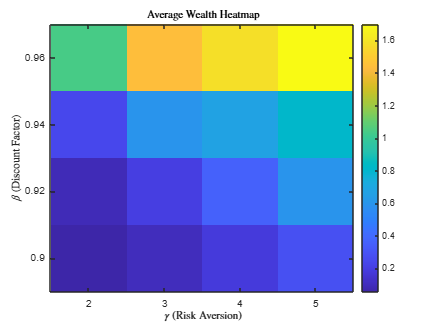


% Plot heatmap
my_graph.plot_heatmap(avg_wealth_matrix, betas_heat, gammas_heat);

## Extended model: Model with education factor

The representative household lives up to age:


$$ \(T - 1\). It works and receives exogenous labor income, \(y_t\), for the first \(tr - 1\) years of life. The labor income during the working period is influenced by the household's education level (\(E\)), which ranges from 0 (no formal education) to 12 (highest educational attainment). The education level impacts income through the multiplier \(\psi\), defined as:

\[
\psi = 1 + \frac{E}{12} \times \alpha
\]

From age \(t_r\) onward, the household retires and receives a pension equal to some fraction, \(0 < \kappa < 1\), of the labor income in the last year of working life, \(y_{tr-1}\). The modified income equation considering the education determinant is given by:
\[
y_t = 
\begin{cases} 
(1 + \frac{E}{12} \times \alpha) \times G_t \times e^{(\rho \log y_{t-1} + \epsilon_t)} & \text{if } t < tr \\
\kappa \times y_{tr-1} & \text{if } t \geq tr 
\end{cases}
\]
The optimization problem:
\[
\max \sum_{t=0}^{T-1} \beta^t \frac{c_t^{1-\gamma}}{1-\gamma}
\]

\text{Subject to:}
\[
a_{t+1} = (1 + r) \times (a_t + y_t - c_t)
\]
\[
y_t = 
\begin{cases} 
(1 + \frac{E}{12} \times \alpha) \times G_t \times e^{(\rho \log y_{t-1} + \epsilon_t)} & \text{if } t < tr \\
\kappa \times y_{tr-1} & \text{if } t \geq tr 
\end{cases}
\]
    \[
    a_t \geq 0
    \]
    \[
    c_t > 0
    \]
    \[
    a_T = 0
    \]

    \[
    a_0 \geq 0
    \]$$


% Load raw Gₜ (Age-Income Only)
[Gt_bin, Edist, Gt_matrix] = prepare_income("household_data.csv");

Alpha not provided, using default value: 0.50
Education Distribution:
Education Level 0: 21.57%
Education Level 1: 27.67%
Education Level 2: 31.93%
Education Level 3: 14.10%
Education Level 4: 0.00%
Education Level 5: 0.00%
Education Level 6: 0.00%
Education Level 7: 0.00%
Education Level 8: 0.82%
Education Level 9: 3.63%
Education Level 10: 0.13%
Education Level 11: 0.07%
Education Level 12: 0.07%

Education Multiplier (ψ) for α = 0.50:
Education Level 0: ψ = 1.000
Education Level 1: ψ = 1.042
Education Level 2: ψ = 1.083
Education Level 3: ψ = 1.125
Education Level 4: ψ = 1.167
Education Level 5: ψ = 1.208
Education Level 6: ψ = 1.250
Education Level 7: ψ = 1.292
Education Level 8: ψ = 1.333
Education Level 9: ψ = 1.375
Education Level 10: ψ = 1.417
Education Level 11: ψ = 1.458
Education Level 12: ψ = 1.500

Age and Education Specific Income (Gt_matrix):
   1.0e+05 *

    0.2053    0.2053    0.3236    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.2053    0.

### Life cycle profiles of consumption and wealth with education-included model

% Interpolate Gₜ for simulation (ages 0–60) - Education Model
age_grid = 0:60;
Gt_interp = interp1(Gt_bin.AgeBin, Gt_bin.Gt, age_grid, 'linear', 'extrap');

% Setup the model parameters for the education-enhanced model
par = model.setup();
par.Gt = Gt_interp(:);  % Ensure Gt has 61 elements
par.Gt_matrix = Gt_matrix;
par.age_bins = Gt_bin.AgeBin;
par.Edist = Edist;
par = model.gen_grids(par);  % Generate asset grid

% Run education-enhanced model
sol = solve.lc(par);

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------


sim = simulate.lc_edu(par, sol);


Education-Enhanced Model Simulation Completed.


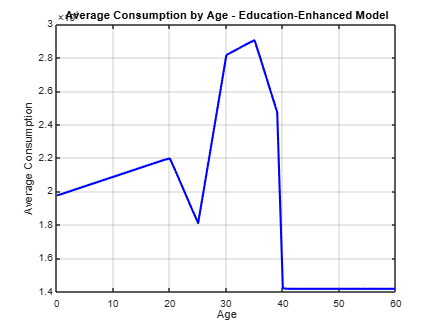

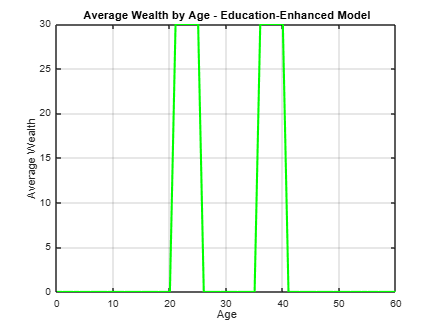

my_graph.plot_lifecycle_profiles(par, sim, 'Education-Enhanced Model');

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


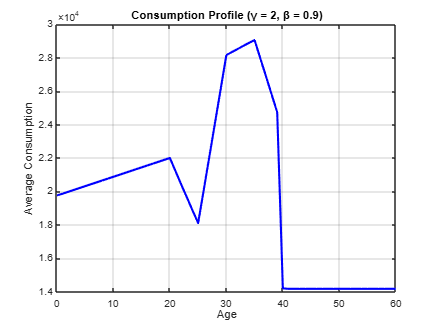

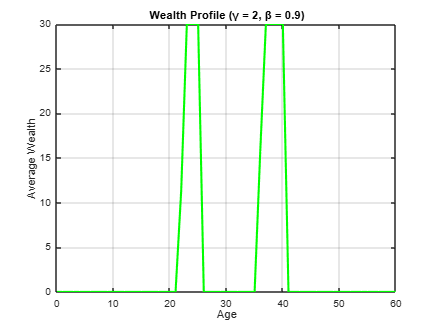

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


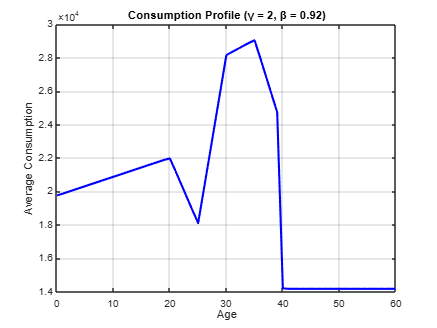

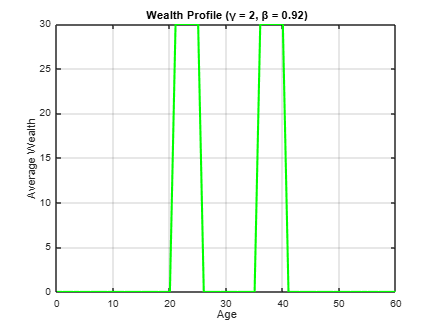

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


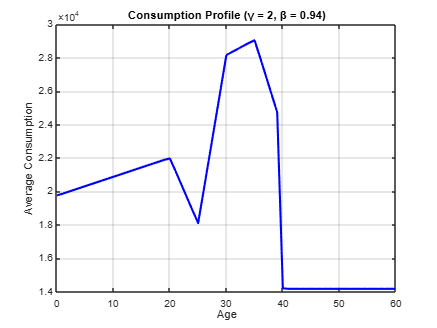

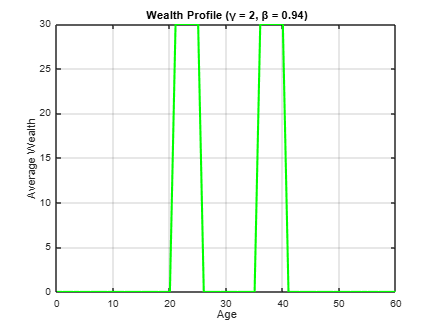

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


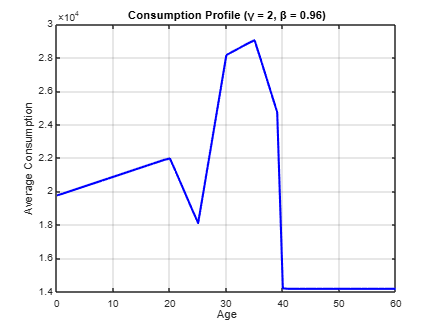

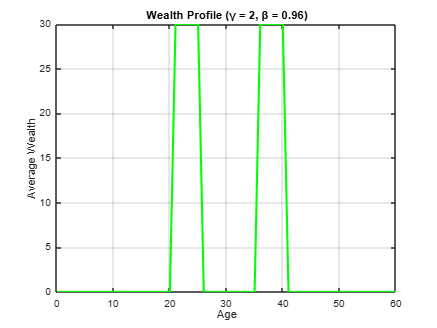

%% Part 1: Vary beta (gamma = 2.00), four separate graphs
gamma_fixed = 2.00;
betas = [0.90, 0.92, 0.94, 0.96];

for i = 1:length(betas)
    par = model.setup();
    par.beta = betas(i);
    par.sigma = gamma_fixed;
    par.Gt = Gt_interp(:);        
    par.Gt_matrix = Gt_matrix;    
    par.age_bins = Gt_bin.AgeBin; 
    par.Edist = Edist;            
    par = model.gen_grids(par);   
    sol = solve.lc(par);
    sim = simulate.lc_edu(par, sol);
    [avg_c, avg_a] = my_graph.average_profiles(par, sim);

    % Plot consumption profile for each beta
    figure;
    plot(0:par.T-1, avg_c, 'b-', 'LineWidth', 2);
    title(['Consumption Profile (γ = ', num2str(gamma_fixed), ', β = ', num2str(betas(i)), ')']);
    xlabel('Age');
    ylabel('Average Consumption');
    grid on;

    % Plot wealth profile for each beta
    figure;
    plot(0:par.T-1, avg_a, 'g-', 'LineWidth', 2);
    title(['Wealth Profile (γ = ', num2str(gamma_fixed), ', β = ', num2str(betas(i)), ')']);
    xlabel('Age');
    ylabel('Average Wealth');
    grid on;
end

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


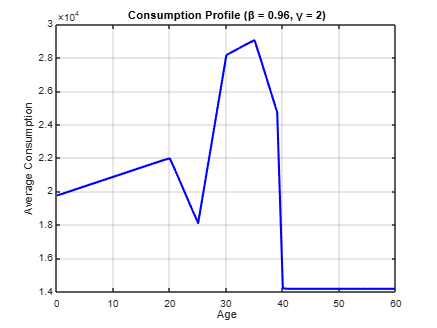

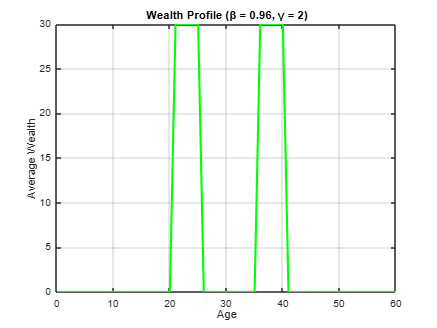

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


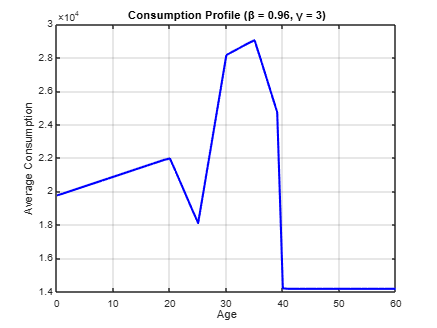

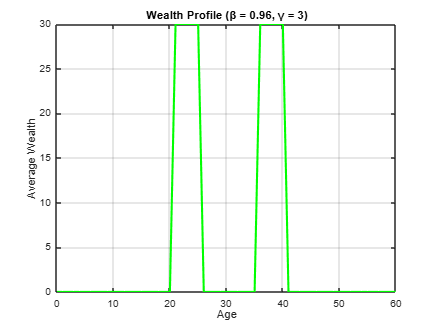

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


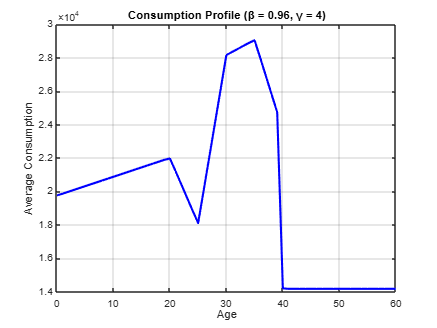

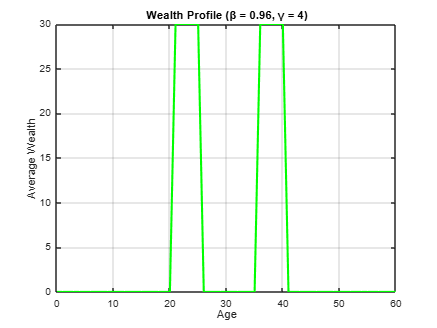

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


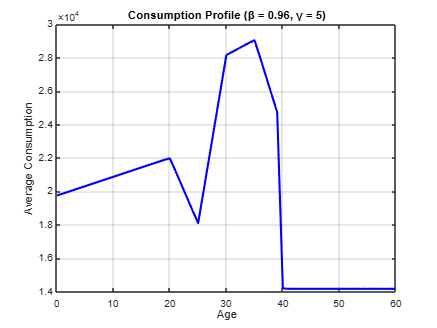

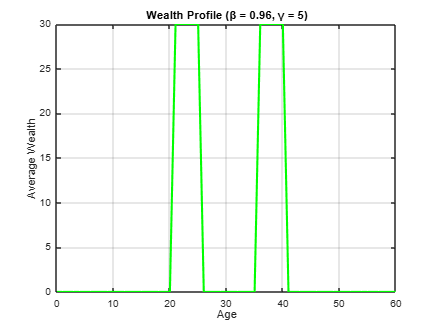

%% Part 2: Vary gamma (beta = 0.96), four separate graphs
beta_fixed = 0.96;
gammas = [2.00, 3.00, 4.00, 5.00];

for j = 1:length(gammas)
    par = model.setup();
    par.beta = beta_fixed;
    par.sigma = gammas(j);
    par.Gt = Gt_interp(:);        
    par.Gt_matrix = Gt_matrix;    
    par.age_bins = Gt_bin.AgeBin; 
    par.Edist = Edist;            
    par = model.gen_grids(par);   
    sol = solve.lc(par);
    sim = simulate.lc_edu(par, sol);
    [avg_c, avg_a] = my_graph.average_profiles(par, sim);

    % Plot consumption profile for each gamma
    figure;
    plot(0:par.T-1, avg_c, 'b-', 'LineWidth', 2);
    title(['Consumption Profile (β = ', num2str(beta_fixed), ', γ = ', num2str(gammas(j)), ')']);
    xlabel('Age');
    ylabel('Average Consumption');
    grid on;

    % Plot wealth profile for each gamma
    figure;
    plot(0:par.T-1, avg_a, 'g-', 'LineWidth', 2);
    title(['Wealth Profile (β = ', num2str(beta_fixed), ', γ = ', num2str(gammas(j)), ')']);
    xlabel('Age');
    ylabel('Average Wealth');
    grid on;
end

%% Part 3: Heatmap (vary both beta and gamma)
betas_heat = [0.90, 0.92, 0.94, 0.96];
gammas_heat = [2.00, 3.00, 4.00, 5.00];
avg_wealth_matrix = zeros(length(betas_heat), length(gammas_heat));

for i = 1:length(betas_heat)
    for j = 1:length(gammas_heat)
        par = model.setup();
        par.beta = betas_heat(i);
        par.sigma = gammas_heat(j);
        par.Gt = Gt_interp(:);        
        par.Gt_matrix = Gt_matrix;    
        par.age_bins = Gt_bin.AgeBin; 
        par.Edist = Edist;            
        par = model.gen_grids(par);   
        sol = solve.lc(par);
        sim = simulate.lc_edu(par, sol);
        avg_wealth = mean(sim.asim(:), 'omitnan');
        avg_wealth_matrix(i, j) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


------------Solving from the Last Period of Life.------------

Solved Age: 59
Solved Age: 54
Solved Age: 49
Solved Age: 44
Solved Age: 39
Solved Age: 34
Solved Age: 29
Solved Age: 24
Solved Age: 19
Solved Age: 14
Solved Age: 9
Solved Age: 4

------------Life Cycle Problem Solved.------------



Education-Enhanced Model Simulation Completed.


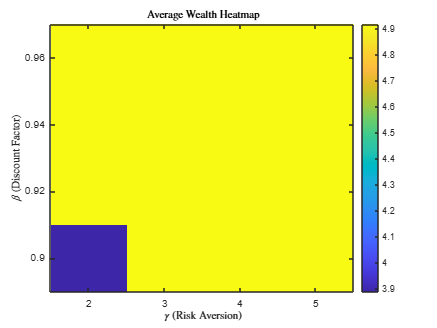

% Plot heatmap of average wealth
my_graph.plot_heatmap(avg_wealth_matrix, betas_heat, gammas_heat);

### Compare the summary statistics and other features in the actual and stimulated data

% Load actual data 
actual_data = readtable('household_data.csv');

% Compute ages
actual_data.AgeBin = floor(actual_data.Age / 5) * 5;

% Group by age bins and variables
actual_stats = varfun(@mean, actual_data, 'InputVariables', {'Income', 'Consumption', 'Wealth'}, ...
                      'GroupingVariables', 'AgeBin');
actual_stats.Var_Consumption = varfun(@var, actual_data, 'InputVariables', {'Consumption'}, ...
                                      'GroupingVariables', 'AgeBin');

% Calculate ratios
actual_stats.ConsumptionToIncome = actual_stats.mean_Consumption ./ actual_stats.mean_Income;
actual_stats.WealthToIncome = actual_stats.mean_Wealth ./ actual_stats.mean_Income;

% Display the result
disp('Actual Data Summary Statistics:');

Actual Data Summary Statistics:


disp(actual_stats);

    AgeBin    GroupCount    mean_Income    mean_Consumption    mean_Wealth                Var_Consumption                ConsumptionToIncome    WealthToIncome
    ______    __________    ___________    ________________    ___________    _______________________________________    ___________________    ______________

                                                                              AgeBin    GroupCount    var_Consumption                                         
                                                                              ______    __________    _______________                               

% Extract statistics from the simulated data
age_bins = 0:60; % Age range

sim_stats = table(age_bins', 'VariableNames', {'AgeBin'});

% Compute Mean and Variance for Simulated Data
sim_stats.Mean_Consumption = mean(sim.csim, 2, 'omitnan');
sim_stats.Mean_Wealth = mean(sim.asim, 2, 'omitnan');
sim_stats.Mean_Income = mean(sim.ysim, 2, 'omitnan');
sim_stats.Var_Consumption = var(sim.csim, 0, 2, 'omitnan');

% Calculate Ratios
sim_stats.ConsumptionToIncome = sim_stats.Mean_Consumption ./ sim_stats.Mean_Income;
sim_stats.WealthToIncome = sim_stats.Mean_Wealth ./ sim_stats.Mean_Income;

% Display
disp('Simulated Data Summary Statistics:');

Simulated Data Summary Statistics:


disp(sim_stats);

    AgeBin    Mean_Consumption    Mean_Wealth    Mean_Income    Var_Consumption    ConsumptionToIncome    WealthToIncome
    ______    ________________    ___________    ___________    _______________    ___________________    ______________

       0           19761               0            25327         1.9065e-21             0.78024                     0  
       1           19873               0            25893         8.0548e-20             0.76751                     0  
       2           19985               0            26213         1.1915e-20             0.76242                     0  
       3           20097               0            26708         3.7189e-20             0.75246                     0  
       4           20209           

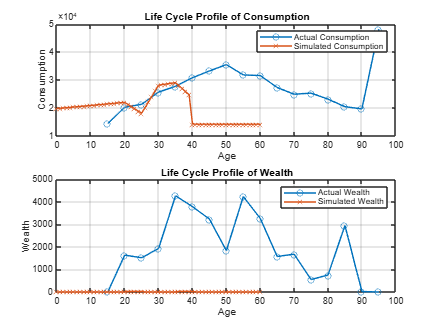

figure;
subplot(2,1,1);
plot(actual_stats.AgeBin, actual_stats.mean_Consumption, '-o', 'DisplayName', 'Actual Consumption');
hold on;
plot(sim_stats.AgeBin, sim_stats.Mean_Consumption, '-x', 'DisplayName', 'Simulated Consumption');
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Profile of Consumption');
legend;
grid on;

subplot(2,1,2);
plot(actual_stats.AgeBin, actual_stats.mean_Wealth, '-o', 'DisplayName', 'Actual Wealth');
hold on;
plot(sim_stats.AgeBin, sim_stats.Mean_Wealth, '-x', 'DisplayName', 'Simulated Wealth');
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Profile of Wealth');
legend;
grid on;

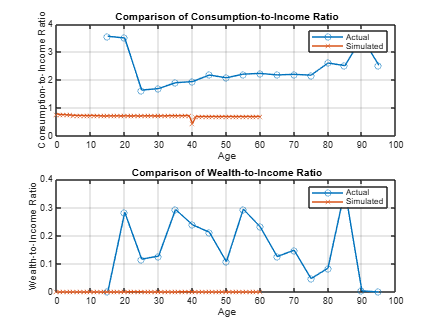

figure;
subplot(2,1,1);
plot(actual_stats.AgeBin, actual_stats.ConsumptionToIncome, '-o', 'DisplayName', 'Actual');
hold on;
plot(sim_stats.AgeBin, sim_stats.ConsumptionToIncome, '-x', 'DisplayName', 'Simulated');
xlabel('Age');
ylabel('Consumption-to-Income Ratio');
title('Comparison of Consumption-to-Income Ratio');
legend;
grid on;

subplot(2,1,2);
plot(actual_stats.AgeBin, actual_stats.WealthToIncome, '-o', 'DisplayName', 'Actual');
hold on;
plot(sim_stats.AgeBin, sim_stats.WealthToIncome, '-x', 'DisplayName', 'Simulated');
xlabel('Age');
ylabel('Wealth-to-Income Ratio');
title('Comparison of Wealth-to-Income Ratio');
legend;
grid on;